clear
close all

## Trabalho Computacional I - Questão 1

**Alunos:**

- Daniel da Rocha Carneiro

- Leon Lima Santos

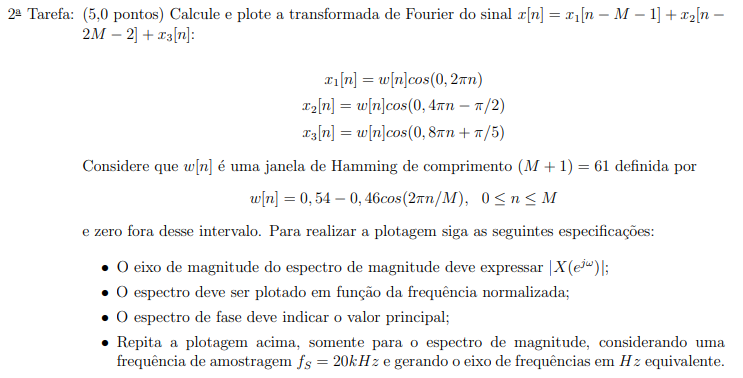

### **Resposta para uma taxa de amostragem Fs**

Inicou-se definindo os parâmetros para análise discreta e definindo os vetores de tempo e frequência normalizada:

Fs = 10;       % Frequência de amostragem em Hz
Fn = Fs/2;                              % Frequência de Nyquist
T = 1/Fs;                               % Período de amostragem       
L = 60*Fs;                              % Duração do sinal
n = (0:L-1)*T;                          % Vetor de tempo
N = numel(n);                           % Tamanho do vetor
Freq = linspace(-Fn, Fn, numel(n));     % Eixo de frequência normalizada




Defini-se também a janela de Hamming, que pode ser implementada via função do Matlab, ou numericamente:

M=60;
l = (M+1);
n1 = n-M-1;
n2 = n-2*M-2;
%w = hamming(M*Fs)';                        % Janela de Hamming via Matlab
%w = (0.54 - 0.46*cos(2*pi*n/M));          % Janela de Hamming numérica

w = hamming(M*Fs)';

E com isso, declarou-se os valores das funções que compõem o sinal x[n]:

x1 = w.*cos(0.2*pi*n1);                % x1[n]
x2 = w.*cos((0.4*pi*n2)-(pi/2));       % x2[n]
x3 = w.*cos((0.8*pi*n)+(pi/5));        % x3[n]

x = x1+x2+x3;                           % x[n]

O sinal x[n] pode ser esboçado da forma a seguir:

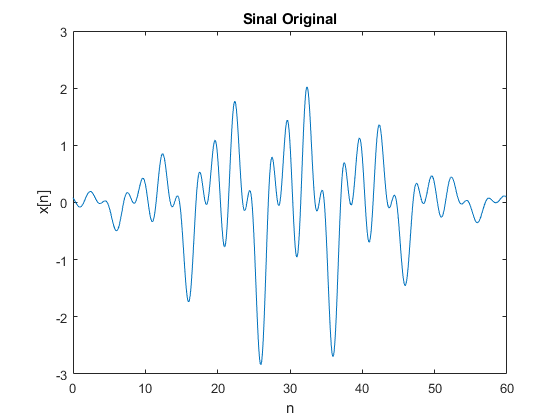

figure
plot(n,x)                                % Pulse
title("Sinal Original")
xlabel("n")
ylabel("x[n]")

Calcula-se a transformada de Fourrier do sinal, utilizando o algoritmo Fast Fourrier Transform:

X = fft(x);

Com a transformada, é possível calcular o espectro de magnitude em função da frequência normalizada:

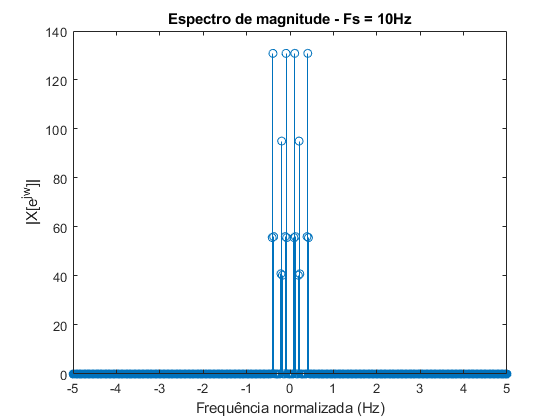

%plot(n,fftshift(real(X)));                     % Função caso x[n] fosse contínuo 
stem(Freq,fftshift(abs(real(X))));              % Utilizado fftshift para centralizar o espectro em torno da frequência 0;
title(sprintf("Espectro de magnitude - Fs = %dHz", Fs))
xlabel("Frequência normalizada (Hz)")
ylabel("|X[e^{jw}]|")

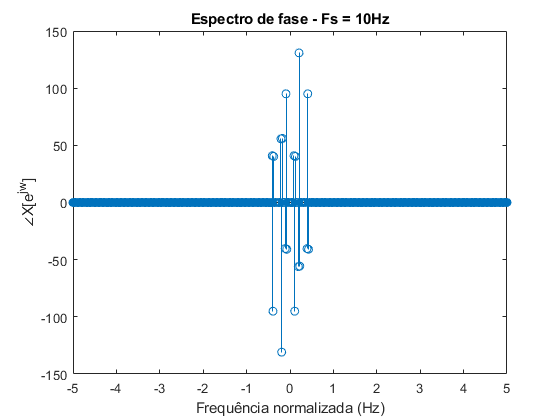

figure
stem(Freq,fftshift(imag(X)));        % Plot discreto
%plot(Freq,fftshift(imag(X)));       % Plot contínuo
title(sprintf("Espectro de fase - Fs = %dHz", Fs))
xlabel("Frequência normalizada (Hz)")
ylabel("∠X[e^{jw}]")

Para facilitar a leitura, implementou-se a função *identificarPicos* para informar os valores diferentes de aproximadamente 0:

a = identificarPicos(imag(X),0.1)

a =   130.8719   95.0869   95.0799   56.0849   55.6568   40.8875   40.8821   40.3063   40.2967         0


### **Espectro de magnitude para 20kHz**

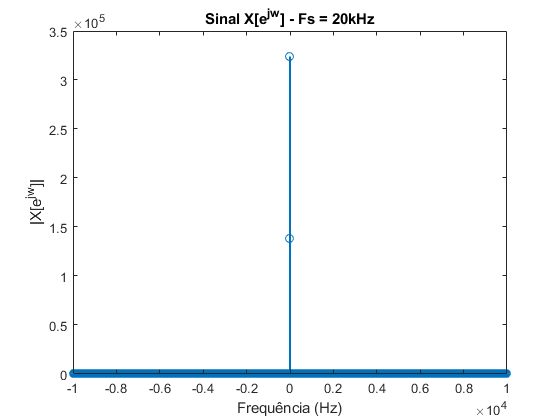

figure
plotMagnitude(20000)

function [picos] = identificarPicos(entrada, limite) % Função para facilitar a identificação dos impulsos encontrados
    entrada(abs(entrada)<limite) = 0;
    picos = findpeaks(entrada);
    picos = sort(picos, 'descend');
end


%% Funções para facilitar a plotagem de sinais para diversas de amostragem diferentes
function plotSinal(Fs, name)
    [x, n, ~, ~] = calculaTransformada(Fs);
    stem(n,x);
    if ~exist("name", "var")
        title(sprintf("Sinal x[n] - Fs = %dHz", Fs))
        if Fs>=1000
            title(sprintf("Sinal x[n] - Fs = %dkHz", Fs/1000))
        end
    else
        title(name)
    end
    xlabel("n (amostras)")
    ylabel("x[n]")
end

function plotMagnitude(Fs, name)
    [~, ~, X, Freq] = calculaTransformada(Fs);
    stem(Freq,fftshift(abs(X)));
    if ~exist("name", "var")
        title(sprintf("Espectro de magnitude - Fs = %dHz", Fs))
        if Fs>=1000
            title(sprintf("Sinal X[e^{jw}] - Fs = %dkHz", Fs/1000))
        end    
    else
        title(name)
    end

    xlabel("Frequência (Hz)")
    ylabel("|X[e^{jw}]|")            
end

function [x, n, X, Freq] = calculaTransformada(Fs)
Fn = Fs/2;                              % Frequência de Nyquist
T = 1/Fs;                               % Período de amostragem
L = 60*Fs;                              % Duração do sinal
n = (0:L-1)*T;                          % Vetor de tempo
N = numel(n);                           % Tamanho do vetor
Freq = linspace(-Fn, Fn, numel(n));     % Eixo de frequência normalizada
M=60;
l = (M+1);
n1 = n-M-1;
n2 = n-2*M-2;
w = hamming(M*Fs)';                     % Janela de Hamming
x1 = w.*cos(0.2*pi*n1);                 % x1[n]
x2 = w.*cos((0.4*pi*n2)-(pi/2));        % x2[n]
x3 = w.*cos((0.8*pi*n)+(pi/5));         % x3[n]
x = x1+x2+x3;                           % x[n]
X = fft(x);
end


